## Задание 4. Задача слежения для системы с астатизмом первого порядка (И-регулятор)

simTimeStart = 0;
simTimeEnd = 50;
step = 0.02;
data.time=(simTimeStart:step:simTimeEnd)';
modelName = 'task4'; 

A = 2;
input = A * ones(1, length(data.time))';
data.signals(1).values=input;
data.signals(1).dimensions=1;

## Стационарный режим работы

### Испытание 1

k = 0.05

k = 0.0500


load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

e_final = A - y_out(end)

e_final = 4.9622e-05

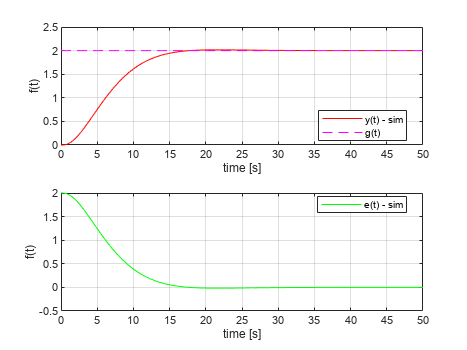


figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
plot(time, A * ones(1, length(time)), 'magenta--');
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, A - y_out, 'g');
hold on;
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp1')

### Испытание 2

k = 0.5

k = 0.5000


load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

e_final = A - y_out(end)

e_final = -0.0038

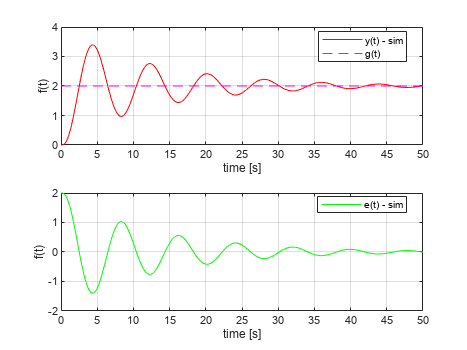


figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, A * ones(1, length(time)), 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, A - y_out, 'g');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp2')

### Испытание 3

k = 0.3

k = 0.3000


load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

e_final = A - y_out(end)

e_final = 0.0017

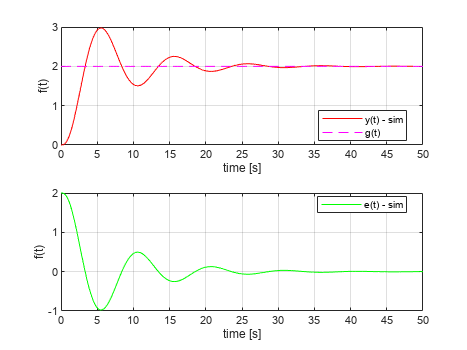


figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, A * ones(1, length(time)), 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, A - y_out, 'g');
hold on;
title(' ');    
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp3')

### Испытание 1,2,3

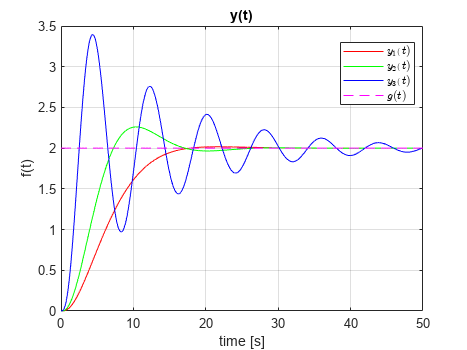

load_system(modelName);
k = 0.05;  
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
k = 0.1;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
k = 0.5;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

%%%    y(t)   %%%
figure;
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, A * ones(1, length(time)), 'magenta--');
title('y(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t)$','$y_2(t)$','$y_3(t)$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task4_exp4')

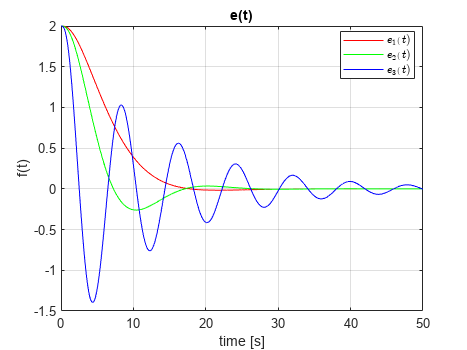


%%%    e(t)   %%%
figure;
plot(time, A - y_out1, 'r');
hold on;
plot(time, A - y_out2, 'g');
hold on;
plot(time, A - y_out3, 'b');
title('e(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t)$','$e_2(t)$','$e_3(t)$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task4_exp5')

## Постоянная скорость -  режим работы

simTimeStart = 0;
simTimeEnd = 60;
step = 0.002;
data.time=(simTimeStart:step:simTimeEnd)';
modelName = 'task4'; 

V = 2;
input = (V .* data.time);
data.signals(1).values = input;
data.signals(1).dimensions = 1;

### Испытание 1

k = 0.5;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

e_final = V*time(end) - y_out(end)

e_final = 1.3309

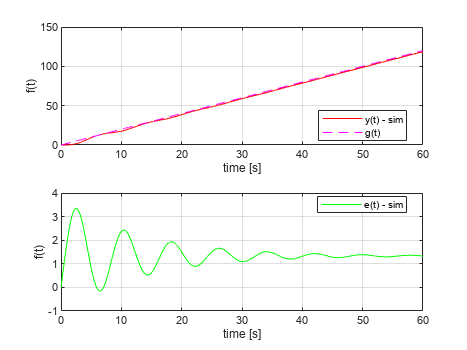


figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, V*time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, V * time - y_out, 'g');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp6')

### Испытание 2

k = 0.05;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

e_final = V*time(end) - y_out(end)

e_final = 13.3333

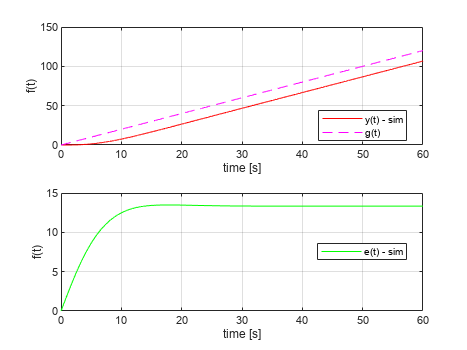


figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, V*time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, V * time - y_out, 'g');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp7')

### Испытание 3

k = 0.1;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

e_final = V*time(end) - y_out(end)

e_final = 6.6666

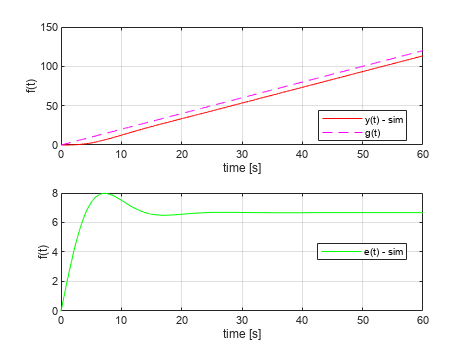


figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, V*time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, V * time - y_out, 'g');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp8')

### Испытание 1,2,3

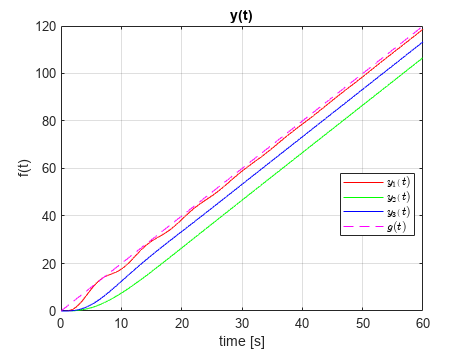

load_system(modelName);
k = 0.5; 
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
k = 0.05;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
k = 0.1;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

%%%    y(t)   %%%
figure;
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, V * time, 'magenta--');
title('y(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t)$','$y_2(t)$','$y_3(t)$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task4_exp9')

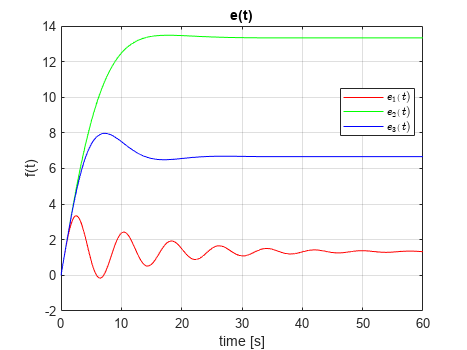


%%%    e(t)   %%%
figure;
plot(time, V * time - y_out1, 'r');
hold on;
plot(time, V * time - y_out2, 'g');
hold on;
plot(time, V * time - y_out3, 'b');
title('e(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t)$','$e_2(t)$','$e_3(t)$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task4_exp10')

## С ускорением - режим работы

simTimeStart = 0;
simTimeEnd = 30;
step = 0.002;
data.time=(simTimeStart:step:simTimeEnd)';
modelName = 'task4'; 

B = 0.5;
input = (B .* data.time .* data.time);
data.signals(1).values = input;
data.signals(1).dimensions = 1;

### Испытание 1

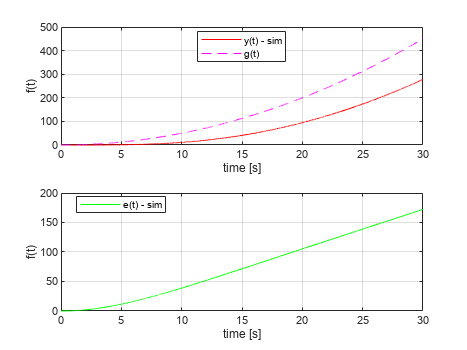

k = 0.05;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, B.*time.*time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, B.*time.*time - y_out, 'g');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp11')

### Испытание 2

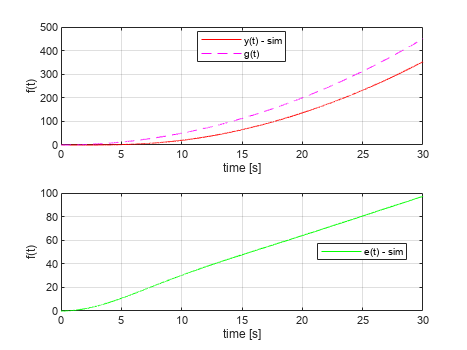

k = 0.1;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, B.*time.*time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, B.*time.*time - y_out, 'g');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp12')

### Испытание 3

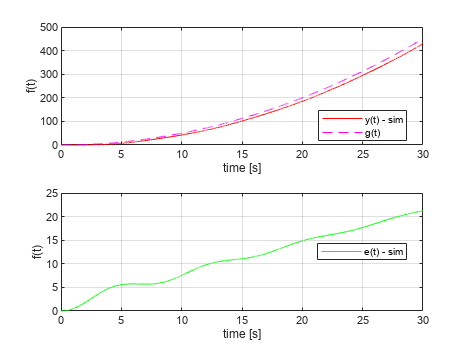

k = 0.5;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, B.*time.*time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim','g(t)', 'Location', 'Best');

subplot(2,1,2);
plot(time, B.*time.*time - y_out, 'g');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('e(t) - sim', 'Location', 'Best');

save_file('output_task4_exp13')

### Испытание 1,2,3

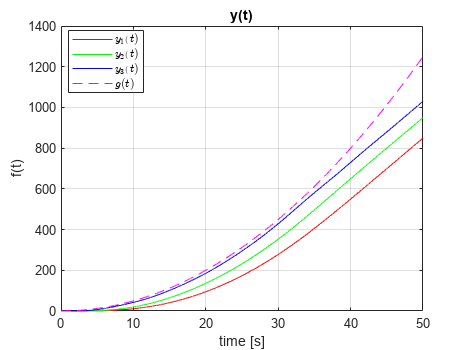

simTimeStart = 0;
simTimeEnd = 50;
step = 0.002;

load_system(modelName);
k = 0.05;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
k = 0.1;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
k = 0.5;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

%%%    y(t)   %%%
figure;
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, B.*time.*time, 'magenta--');
title('y(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t)$','$y_2(t)$','$y_3(t)$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task4_exp14')

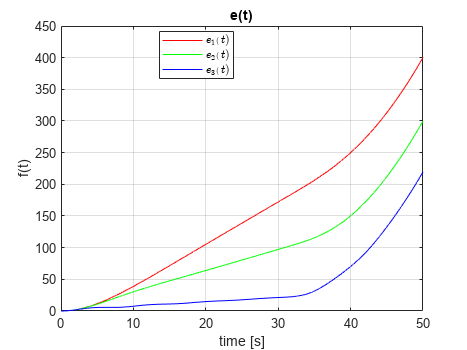


%%%    e(t)   %%%
figure;
plot(time, B.*time.*time - y_out1, 'r');
hold on;
plot(time, B.*time.*time - y_out2, 'g');
hold on;
plot(time, B.*time.*time - y_out3, 'b');
title('e(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t)$','$e_2(t)$','$e_3(t)$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task4_exp15')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab4\latex4\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end